## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

clear all
close all
clc
mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15), 'm', 1.0, 'Ic', 0.5^2 / 12);
mbs = add_body(mbs, "slider", -0.6, 'm', 3.0, 'Ic', 0.1)

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


Get mass matrix

M = mass_matrix(mbs)

M =     2.0000         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0
         0         0    0.0067         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    0.0208         0         0         0
         0         0         0         0         0         0    3.0000         0         0
         0         0         0         0         0         0         0    3.0000         0
         0         0         0         0         0         0         0         0    0.1000


### Forces definition

mbs = add_gravity(mbs, [0, -9.81]);

### Force vector

q0 = initial_position(mbs);
F = forces(mbs, q0)

F =          0
  -19.6200
         0
         0
   -9.8100
         0
         0
  -29.4300
         0


Simple checking for the gravity forces

qpp = M\F

qpp =          0
   -9.8100
         0
         0
   -9.8100
         0
         0
   -9.8100
         0


### Solve system using EulerCromer

Define all the inputs to the system

% [t, U, V] = EulerCromer(accfun, T, U_0, V_0, dt)
accfun = @(t, y)acceleration(mbs,q0,y,t);
qd0 = zeros(size(q0)); % initial velocity
qd0([1, 5]) = -0.1; % Set vx of crank and vy of link
[t y] = ode45(accfun,[0 1],qd0); %return velocity of part
y

y =    -0.1000         0         0         0   -0.1000         0         0         0         0
   -0.1000   -0.0001         0         0   -0.1001         0         0   -0.0001         0
   -0.1000   -0.0001         0         0   -0.1001         0         0   -0.0001         0
   -0.1000   -0.0002         0         0   -0.1002         0         0   -0.0002         0
   -0.1000   -0.0002         0         0   -0.1002         0         0   -0.0002         0
   -0.1000   -0.0005         0         0   -0.1005         0         0   -0.0005         0
   -0.1000   -0.0007         0         0   -0.1007         0         0   -0.0007         0
   -0.1000   -0.0010         0         0   -0.1010         0         0   -0.0010         0
   -0.1000   -0.0012         0         0   -0.1012         0         0   -0.0012         0
   -0.1000   -0.0025         0         0   -0.1025         0         0   -0.0025         0


Z = cumtrapz(t,y); %new integral, velocity to position
Z

Z =          0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0
   -0.0000   -0.0000         0         0   -0.0000         0         0   -0.0000         0


Make some plots to check the results

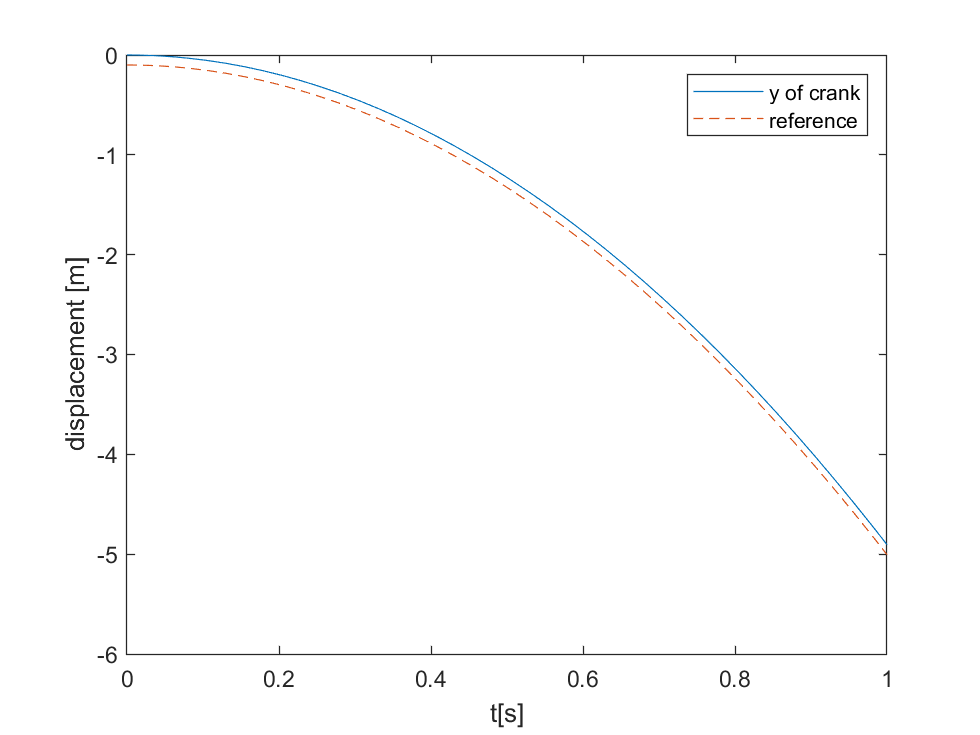

plot(t, Z(:, 2), t, q0(1) + t.*qd0(2) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of crank', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

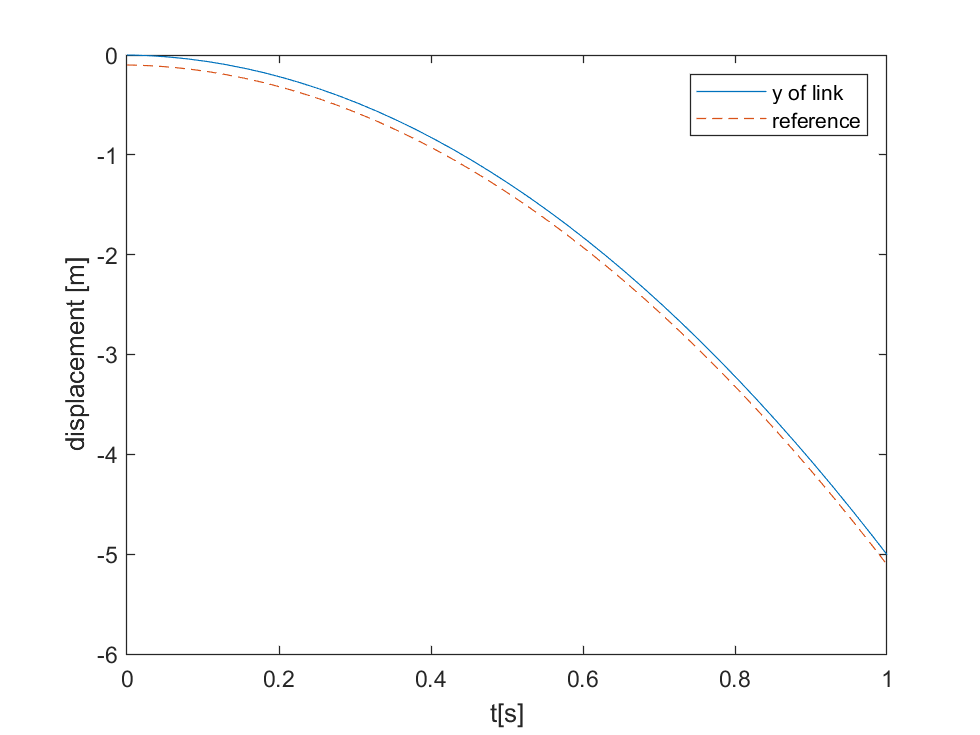

plot(t, Z(:, 5), t, q0(1) + t.*qd0(1) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

## System two - single body with simple constraint under gravity

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "block", 0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_simple_joint(mbs, "blockx", "block", "x", 0.1);


mbs = add_gravity(mbs, [7.12, 12.9]);

q0 = initial_position(mbs);
qd0 = zeros(size(q0));
accfun = @(t, y)acceleration(mbs, qd0, y, t);
[t y] = ode45(accfun,[0 1],q0); %return velocity of part
Z = cumtrapz(t,y) %new integral, velocity to position

Z =          0         0         0
    0.0000    0.0000   -0.0002
    0.0001    0.0001   -0.0004
    0.0001    0.0001   -0.0006
    0.0002    0.0002   -0.0008
    0.0004    0.0004   -0.0018
    0.0006    0.0007   -0.0029
    0.0008    0.0011   -0.0039
    0.0010    0.0015   -0.0049
    0.0022    0.0043   -0.0100


Plot and check

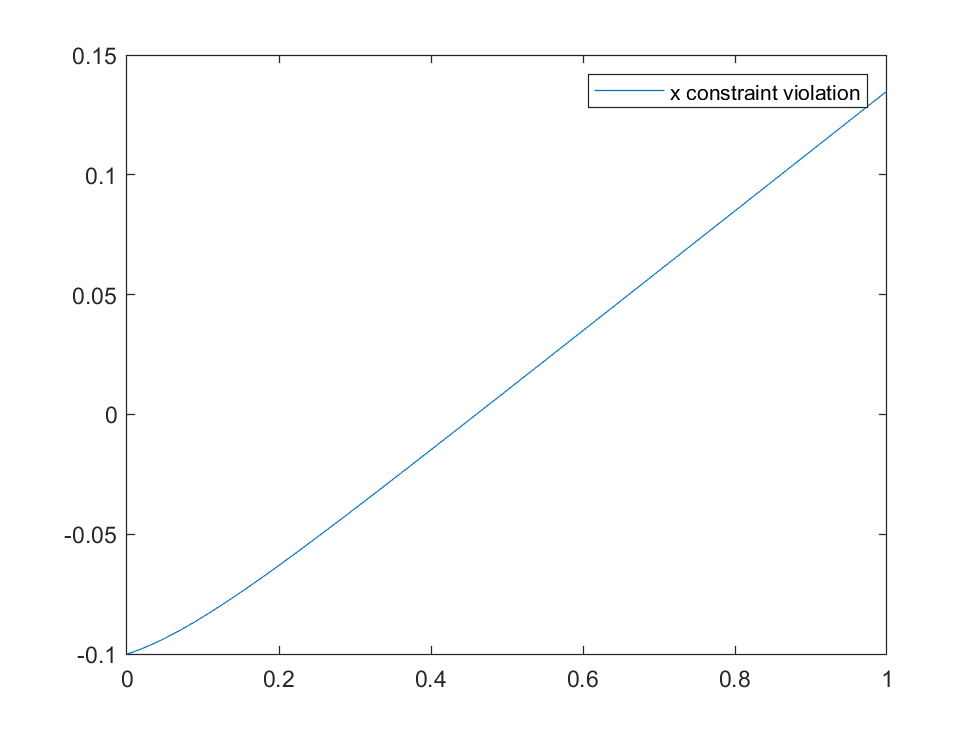

plot(t, Z(:, 1) - q0(1))
legend('x constraint violation')

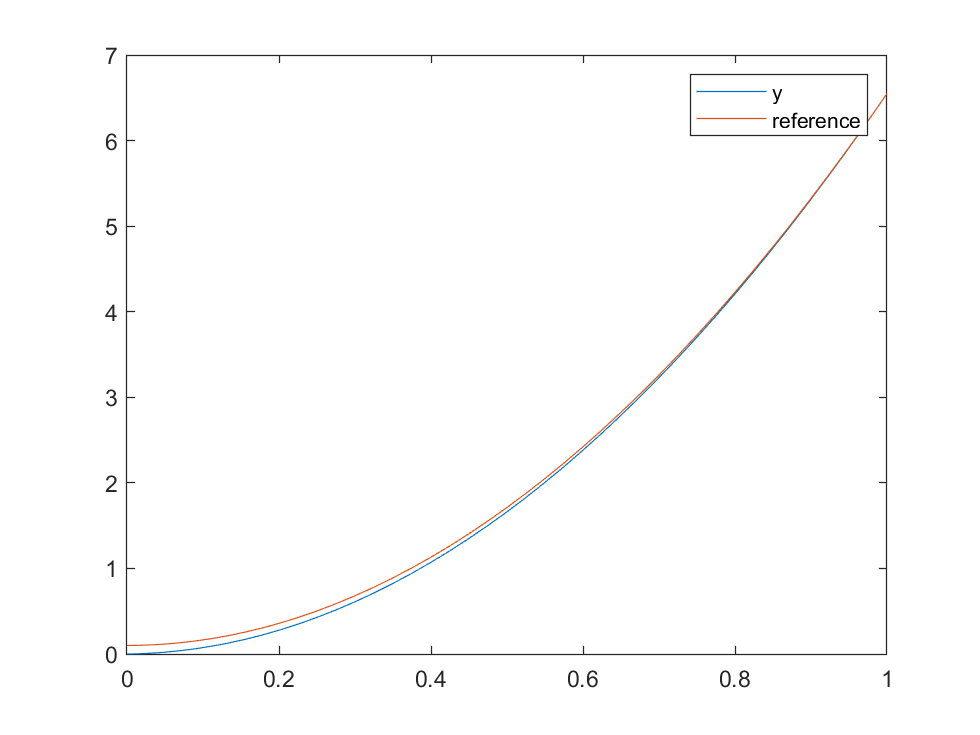

plot(t, Z(:, 2), t, q0(2) + 0.5 * 12.9 .* t.^2)
legend('y', 'reference')

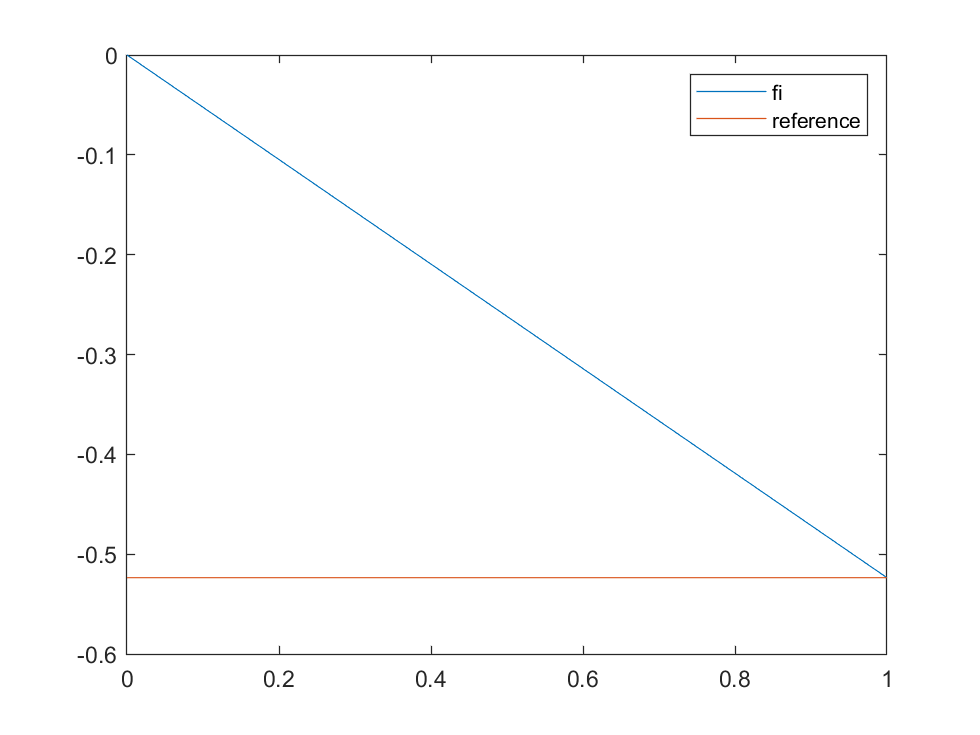

plot(t, Z(:, 3), t, q0(3) * ones(size(t)))
legend('fi', 'reference')